clc; clear; close all;

d =  4; % Number of Gram polynomial interpolation points
C = 27; % Number of continuation points
n_r = 6;

if(exist(['FC_data/A_d',num2str(d),'_C', num2str(C), '_r', num2str(n_r), '.mat']) == 0 | ...
   exist(['FC_data/Q_d',num2str(d),'_C', num2str(C),  '_r', num2str(n_r), '.mat']) == 0)
    disp('FC data not found. Generating FC operators... \n');
    generate_bdry_continuations(d, C, C, 12, 20, 4, ...
        256, n_r);
end

load(['FC_data/A_d',num2str(d),'_C', num2str(C), '_r', num2str(n_r), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(C),  '_r', num2str(n_r), '.mat']);

A_refined = double(A);
Q_refined = double(Q);

load(['FC_data/A_d',num2str(d),'_C', num2str(27), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(27), '.mat']);
A_unrefined = double(A);
Q_unrefined = double(Q);

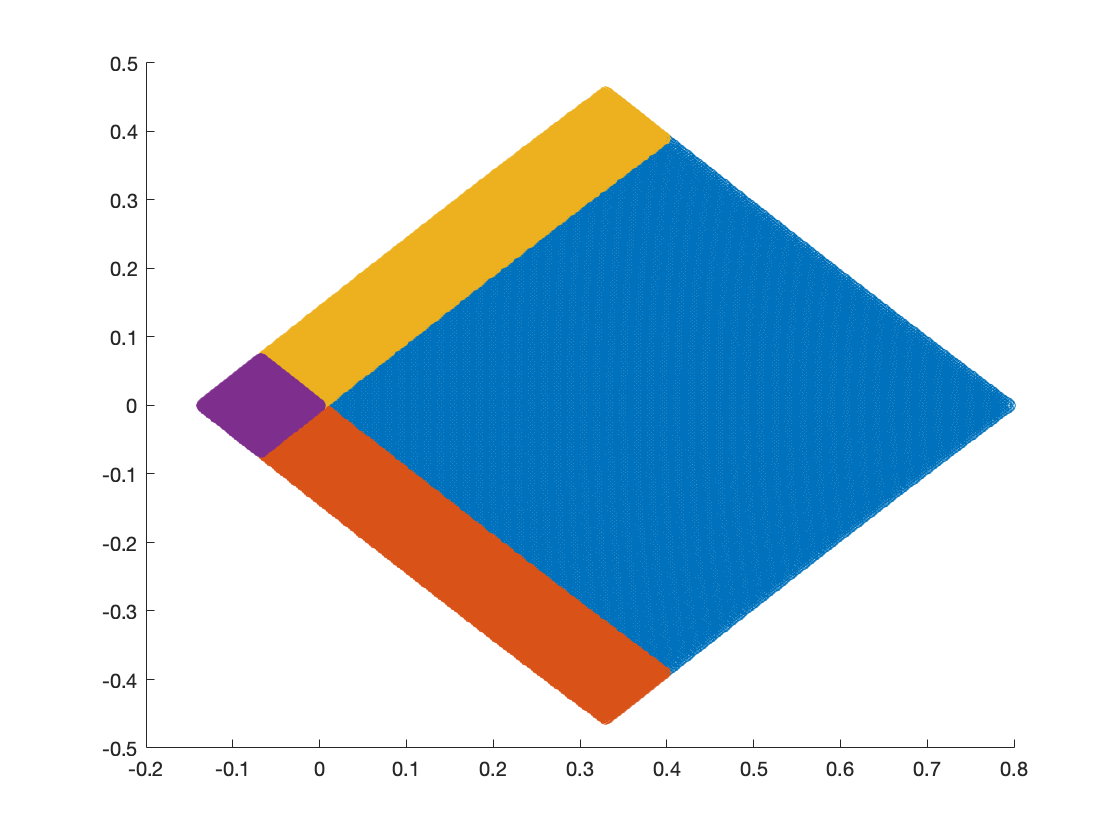

factor = 3;
n_C2 = 20*2^factor;
h = 0.029*(1/2)^factor;

C2_patch = construct_C2_patch(@(x, y) f(x, y), 0.4, 2*pi-0.4, 0, n_C2, n_C2);
[C2_fcont_patch_xi, C2_fcont_patch_eta, C2_fcont_patch_corner] = C2_patch.FC(C, n_r, d, A_refined, Q_refined, nan);

C2_patch_old = construct_C2_patch_old(@(x, y) f(x, y), 0.4, 2*pi-0.4, 0, n_C2, n_C2);
C2_fcont_patch_old = C2_patch_old.FC(C, d, A_unrefined, Q_unrefined, nan);

figure;
[X, Y] = C2_patch.xy_mesh();
scatter(X(:), Y(:));
hold on;
[X, Y] = C2_fcont_patch_xi.xy_mesh();
scatter(X(:), Y(:));
[X, Y] = C2_fcont_patch_eta.xy_mesh();
scatter(X(:), Y(:));
[X, Y] = C2_fcont_patch_corner.xy_mesh();
scatter(X(:), Y(:));

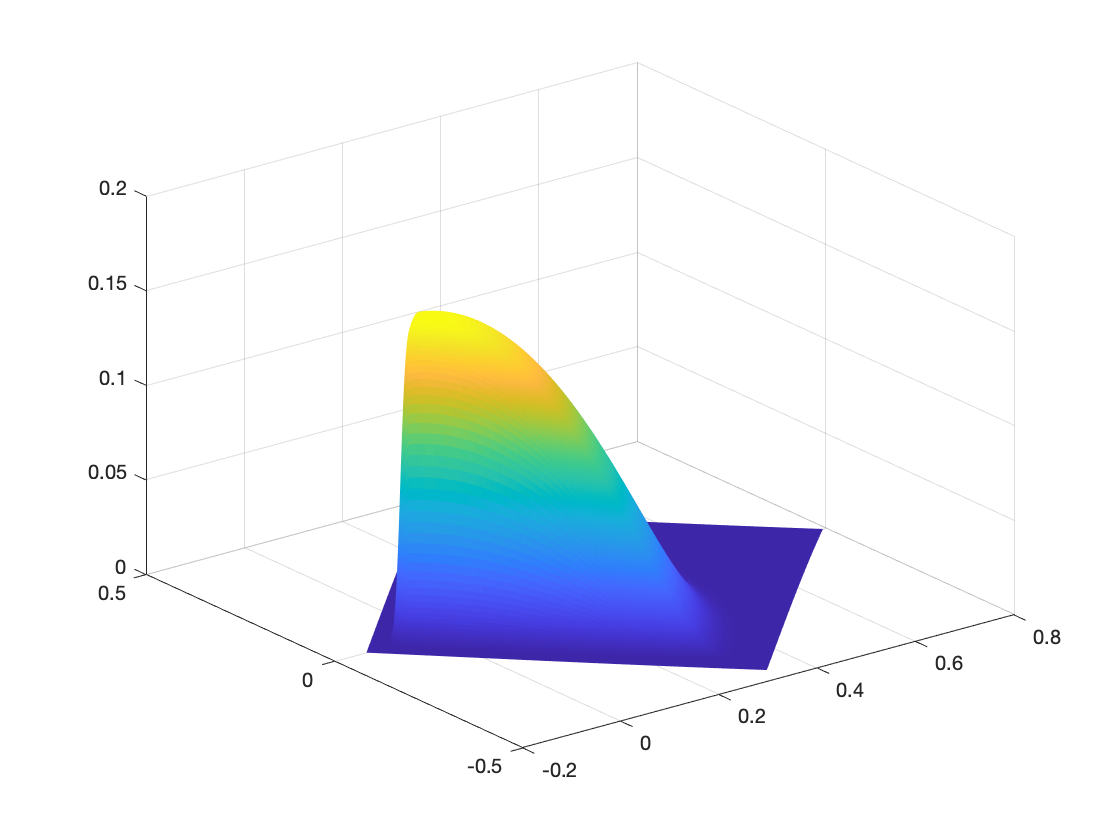


figure;
[X, Y] = C2_patch.xy_mesh();
s = surf(X, Y, C2_patch.f_XY);
s.EdgeColor = 'none';
hold on;

[X, Y] = C2_fcont_patch_xi.xy_mesh();
s = surf(X, Y, C2_fcont_patch_xi.f_XY);
s.EdgeColor = 'none';

[X, Y] = C2_fcont_patch_eta.xy_mesh();
s = surf(X, Y, C2_fcont_patch_eta.f_XY);
s.EdgeColor = 'none';

[X, Y] = C2_fcont_patch_corner.xy_mesh();
s = surf(X, Y, C2_fcont_patch_corner.f_XY);
s.EdgeColor = 'none';

[C2_bound_X, C2_bound_Y] = C2_patch.boundary_mesh_xy();
R_poly = R_cartesian_mesh_obj(C2_fcont_patch_corner.x_min, C2_patch.x_max, C2_fcont_patch_xi.y_min, C2_fcont_patch_eta.y_max, h, C2_bound_X, C2_bound_Y);
R_poly.interpolate_patch(C2_fcont_patch_xi, 8, false);

start first pass
construct nan map


R_poly.interpolate_patch(C2_fcont_patch_eta, 8, false);

start first pass
construct nan map


R_poly.interpolate_patch(C2_fcont_patch_corner, 8, false);

start first pass
construct nan map


R_poly.fill_interior(@(x, y) f(x, y));

R_poly.compute_fc_coeffs();

save("R_poly", "R_poly")

[R_X_err, R_Y_err, f_interpolation, interior_idx] = R_poly.ifft_interpolation(R_poly.h./2);

max(abs(f(R_X_err(interior_idx), R_Y_err(interior_idx))-f_interpolation(interior_idx)))

ans = 3.1165e-10

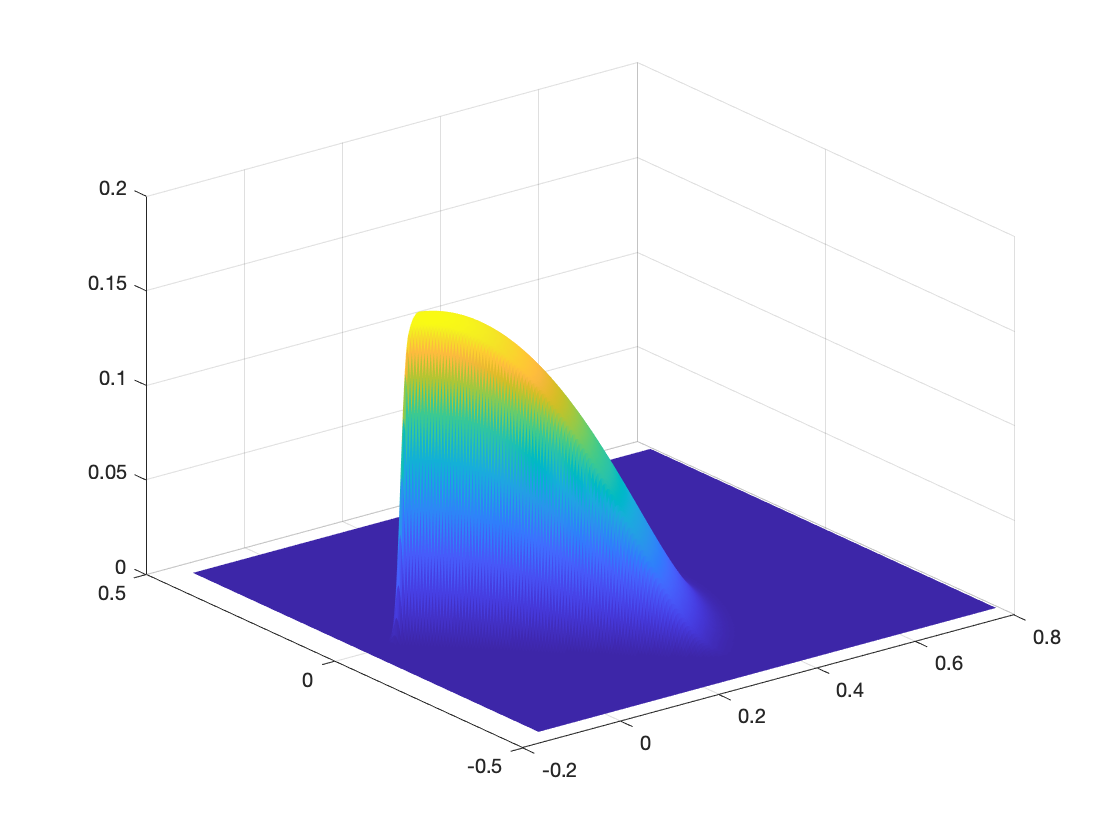


figure;
s = surf(R_poly.R_X, R_poly.R_Y, R_poly.f_R);
s.EdgeColor = 'none';

for vert_idx = 1:C
    [XI, ETA] = C2_fcont_patch_old.xi_eta_mesh;
% figure;
% plot(ETA(C+1:end, vert_idx), C2_fcont_patch_old.f_XY(C+1:end, vert_idx), 'x')
% hold on;
% 
% [XI, ETA] = C2_fcont_patch_eta.xi_eta_mesh;
% plot(ETA(:, vert_idx), C2_fcont_patch_eta.f_XY(:, 6*vert_idx-5), 'o')

    max(abs(C2_fcont_patch_old.f_XY(C+1:end, vert_idx) - C2_fcont_patch_eta.f_XY(:, 6*vert_idx-5)))
end

ans = 3.8519e-34

ans = 1.5777e-30

ans = 4.0390e-28

ans = 2.5849e-26

ans = 8.2718e-25

ans = 5.2940e-23

ans = 0

ans = 6.7763e-21

ans = 0

ans = 1.0842e-19

ans = 8.6736e-19

ans = 3.4694e-18

ans = 6.9389e-18

ans = 1.3878e-17

ans = 2.7756e-17

ans = 5.5511e-17

ans = 5.5511e-17

ans = 8.3267e-17

ans = 5.5511e-17

ans = 5.5511e-17

ans = 5.5511e-17

ans = 5.5511e-17

ans = 5.5511e-17

ans = 2.7756e-17

ans = 2.7756e-17

ans = 2.7756e-17

ans = 2.7756e-17

ans =    -0.3375   -0.3250   -0.3125   -0.3000   -0.2875   -0.2750   -0.2625   -0.2500   -0.2375   -0.2250   -0.2125   -0.2000   -0.1875   -0.1750   -0.1625   -0.1500   -0.1375   -0.1250   -0.1125   -0.1000   -0.0875   -0.0750   -0.0625   -0.0500   -0.0375   -0.0250   -0.0125   -0.0000    0.0125    0.0250    0.0375    0.0500    0.0625    0.0750    0.0875    0.1000    0.1125    0.1250    0.1375    0.1500    0.1625    0.1750    0.1875    0.2000    0.2125    0.2250    0.2375    0.2500    0.2625    0.2750


ans =    -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375


ans =    -0.3375   -0.3354   -0.3333   -0.3313   -0.3292   -0.3271   -0.3250   -0.3229   -0.3208   -0.3188   -0.3167   -0.3146   -0.3125   -0.3104   -0.3083   -0.3063   -0.3042   -0.3021   -0.3000   -0.2979   -0.2958   -0.2938   -0.2917   -0.2896   -0.2875   -0.2854   -0.2833   -0.2812   -0.2792   -0.2771   -0.2750   -0.2729   -0.2708   -0.2688   -0.2667   -0.2646   -0.2625   -0.2604   -0.2583   -0.2563   -0.2542   -0.2521   -0.2500   -0.2479   -0.2458   -0.2438   -0.2417   -0.2396   -0.2375   -0.2354


ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


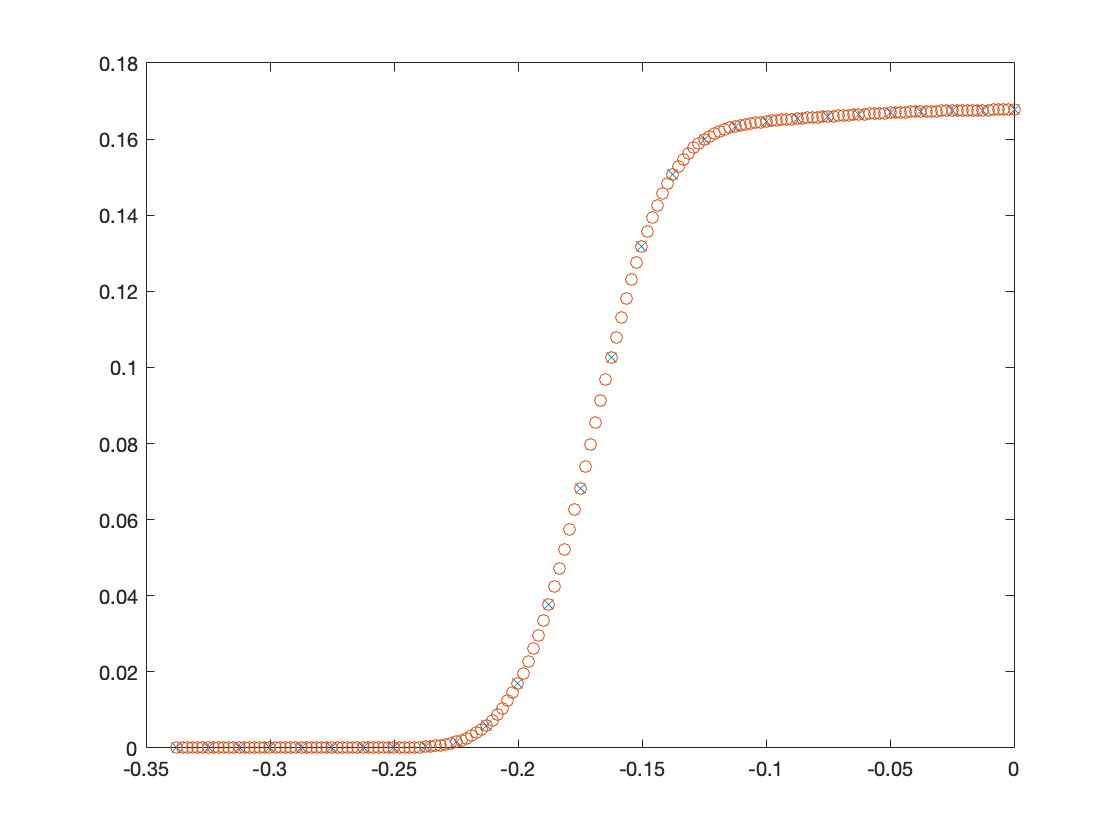

for horz_idx = 1
    [XI, ETA] = C2_fcont_patch_old.xi_eta_mesh;
    figure;
    plot(XI(horz_idx+C, 1:28), C2_fcont_patch_old.f_XY(horz_idx+C, 1:28), 'x')
    hold on;
    
    XI(horz_idx, :)
    ETA(horz_idx, :)
% figure;
% plot(ETA(C+1:end, vert_idx), C2_fcont_patch_old.f_XY(C+1:end, vert_idx), 'x')
% hold on;
% 
    [XI, ETA] = C2_fcont_patch_eta.xi_eta_mesh;
    XI(horz_idx, :)
    ETA(horz_idx, :)
% plot(ETA(:, vert_idx), C2_fcont_patch_eta.f_XY(:, 6*vert_idx-5), 'o')
    plot(XI(horz_idx, :), C2_fcont_patch_eta.f_XY(horz_idx, :), 'o')
end

% clc; clear; close all;
% load("R_FFT.mat")
% load("R_poly.mat")
% 
% figure;
% s = surf(R_FFT.R_X, R_FFT.R_Y, R_poly.f_R);
% s.EdgeColor = 'none'
% 
% figure;
% scatter3(R_FFT.R_X(:), R_FFT.R_Y(:), abs(R_poly.f_R(:)-R_FFT.f_R(:)));
% 
% err = abs(R_poly.f_R-R_FFT.f_R);
% figure;
% scatter(R_FFT.R_X(:), R_FFT.R_Y(:), 100, err(:), 'filled');
% 
% % Add a color bar
% colorbar;
% 
% % Set colormap
% colormap(jet);


function C2_patch = construct_C2_patch(f, theta_A, theta_B, theta_C, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) xi*(theta_A - theta_C) + theta_C;
    l_B = @(eta) eta*(theta_B - theta_C - 2*pi) + theta_C + 2*pi; % account for wrap around
    
    M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
    J = @(v) [theta_A*cos(v(1)*theta_A/2) (theta_B-2*pi)*cos((v(2)*(theta_B-2*pi)+2*pi)/2); -theta_A*cos(v(1)*theta_A) -(theta_B-2*pi)*cos(v(2)*(theta_B-2*pi)+2*pi)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p(XI(:), ETA(:));
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    C2_patch = C2_patch_obj(M_p, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, nan); % data associated with patch
end

function C2_patch = construct_C2_patch_old(f, theta_A, theta_B, theta_C, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) xi*(theta_A - theta_C) + theta_C;
    l_B = @(eta) eta*(theta_B - theta_C - 2*pi) + theta_C + 2*pi; % account for wrap around
    
    M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
    J = @(v) [theta_A*cos(v(1)*theta_A/2) (theta_B-2*pi)*cos((v(2)*(theta_B-2*pi)+2*pi)/2); -theta_A*cos(v(1)*theta_A) -(theta_B-2*pi)*cos(v(2)*(theta_B-2*pi)+2*pi)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p(XI(:), ETA(:));
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    C2_patch = C2_patch_old_obj(M_p, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, nan); % data associated with patch
end

function f_y = f(x, y)
    r = sqrt(x.^2 + y.^2);
    f_y = zeros(size(x));
    f_y(r < 0.56) = exp(1./(1/0.56*r(r < 0.56).^2-0.56));
    f_y(r >= 0.56) = 0;
end

function f_y = f_smooth(x, y)
    f_y = zeros(size(x));
    interior_msk = x < 1 & x > 0 & y < 1 & y > 0;
    f_y(interior_msk) = exp(-1./(1-(2*x(interior_msk)-1).^2)).*exp(-1./(1-(2*y(interior_msk)-1).^2));
end